%% Setup workspace
% Set parameters
ops.timewin = -1000:5000;
ops.bl_win = -150:-50;
ops.freq = [2 200];
ops.sdf_filter = 'PSP';
ops.sig_threshold = 2;
ops.min_sig_time = 50;
ops.freq = [2 60];

% Set parameters for sound specific stimuli
ops.sound_sdf_window = -200:600;
sound_onset_ms = [0, 563, 1126, 1689, 2252];
zero_offset = abs(ops.timewin(1));

% Define neurons
auditory_neuron_idx = find(strcmp(spike_log.area,'R') | strcmp(spike_log.area,'A1') | strcmp(spike_log.area,'RM')  | strcmp(spike_log.area,'dSTS'));
frontal_neuron_idx = find(strcmp(spike_log.area,'44') | strcmp(spike_log.area,'45') | strcmp(spike_log.area,'FOP'));

%% Extract sound aligned Spike Density Function (SDF)
% Load data
neuron_count = 0; lfp_count = 0; % Initialize counters for neurons and LFPs

% Loop through each session in the ephysLog
for session_i = 1:size(ephysLog,1)

    % Load the session data file
    datafile = ephysLog.session{session_i};
    load(fullfile(dirs.mat_data,datafile))
    fprintf('Session %i of %i | %s \n', session_i, size(ephysLog,1), datafile)

    % Adjust stimulus onset times based on session-specific audio latency measures
    for trial_i = 1:size(event_table,1)
        event_table.stimulusOnset_ms(trial_i) = event_table.stimulusOnset_ms(trial_i) + session_audio_latency{session_i}(trial_i,1) - 50;
    end

    % Create a violation alignment event for SDF based on condition value
    for trial_i = 1:size(event_table,1)
        switch event_table.cond_value(trial_i)
            case {3, 7, 14} % Conditions with violation time of 1127 ms
                event_table.violation_ms(trial_i) =  event_table.stimulusOnset_ms(trial_i) + 1127;
            case {4, 8, 15} % Conditions with violation time of 2253 ms
                event_table.violation_ms(trial_i) =  event_table.stimulusOnset_ms(trial_i) + 2253;
            case {1, 5, 13} % Conditions with violation time of 1127 ms
                event_table.violation_ms(trial_i) =  event_table.stimulusOnset_ms(trial_i) + 1127;
            case {2, 6, 16} % Conditions with violation time of 2253 ms
                event_table.violation_ms(trial_i) =  event_table.stimulusOnset_ms(trial_i) + 2253;
            case {9, 10, 11, 12} % Conditions without violation
                event_table.violation_ms(trial_i) =  NaN;
        end
    end

    % Find all neurons recorded in the current session
    neuron_list = spike_log.unitDSP(strcmp(spike_log.session,datafile));

    % Align spikes and generate SDF for different event types
    % - trial start alignment
    aligntime = event_table.trialStart_ms;
    [sdf_trialstart, raster_trialstart] = get_spikes_aligned(spikes,aligntime,ops);
    % - sequence onset alignment
    aligntime_viol = event_table.stimulusOnset_ms;
    [sdf_sequence, raster_sequence] = get_spikes_aligned(spikes,aligntime_viol,ops);
    % - violation onset alignment
    aligntime_viol = event_table.violation_ms;
    [sdf_viol, raster_viol] = get_spikes_aligned(spikes,aligntime_viol,ops);
    % - reward onset alignment
    aligntime_reward = event_table.rewardOnset_ms;
    [sdf_rwd, raster_rwd] = get_spikes_aligned(spikes,aligntime_viol,ops);

    % Process each neuron in the session
    for neuron_i = 1:length(neuron_list)
        neuron_label = neuron_list{neuron_i}; % Get the neuron label
        neuron_count = neuron_count + 1; % Increment the neuron count
        sound_sdf = {}; % Initialize sound SDF cell array
        count = 0; % Initialize counter for sound SDF
        % Store SDFs for different alignment events
        neuron_sdftrialstart_out{neuron_count,1} = sdf_trialstart.(neuron_label);
        neuron_sdfviol_out{neuron_count,1} = sdf_viol.(neuron_label);
        neuron_sdfstimulus_out{neuron_count,1} = sdf_sequence.(neuron_label);
        neuron_sdfreward_out{neuron_count,1} = sdf_rwd.(neuron_label);

        % Process each trial for the current neuron
        for trial_i = 1:size(event_table,1)
            if ~strcmp(event_table.cond_label(trial_i),'error') % Skip error trials
                for sound_i = 1:5 % Loop through each sound in the trial
                    count = count + 1;
                    % Extract and store relevant SDF information for each sound
                    sound_sdf{count,1} = sdf_sequence.(neuron_label)(trial_i,zero_offset+ops.sound_sdf_window+sound_onset_ms(sound_i));
                    sound_sdf{count,2} = raster_sequence.(neuron_label){trial_i}-sound_onset_ms(sound_i);
                    sound_sdf{count,3} = stimulusLog.(['sound_' int2str(sound_i) '_code']){event_table.cond_value(trial_i)};
                    sound_sdf{count,4} = ['position_' int2str(sound_i)];
                    sound_sdf{count,5} = event_table.cond_label(trial_i);
                end
            end
        end

        % Store the sound aligned SDF for the current neuron
        neuron_sdfsound_out{neuron_count} = sound_sdf;
        % Calculate and store the baseline activity for the current neuron
        neuron_baseline(neuron_count,:) = nanmean(sdf_trialstart.(neuron_label)(:,zero_offset+ops.bl_win));
    end
end

%% Normalize activity across sounds
% Loop through each neuron in the spike log
for neuron_i = 1:size(spike_log,1)
    fprintf('Normalizing activity for neuron %i of %i... \n', neuron_i, size(spike_log,1))
    
    % Identify trials for each sound type (A, C, G, F, D)
    a_trials = strcmp(neuron_sdfsound_out{neuron_i}(:,3),'A') & strcmp(string(neuron_sdfsound_out{neuron_i}(:,5)) ,'nonviol');
    c_trials = strcmp(neuron_sdfsound_out{neuron_i}(:,3),'C') & strcmp(string(neuron_sdfsound_out{neuron_i}(:,5)) ,'nonviol');
    g_trials = strcmp(neuron_sdfsound_out{neuron_i}(:,3),'G') & strcmp(string(neuron_sdfsound_out{neuron_i}(:,5)) ,'nonviol');
    f_trials = strcmp(neuron_sdfsound_out{neuron_i}(:,3),'F') & strcmp(string(neuron_sdfsound_out{neuron_i}(:,5)) ,'nonviol');
    d_trials = strcmp(neuron_sdfsound_out{neuron_i}(:,3),'D') & strcmp(string(neuron_sdfsound_out{neuron_i}(:,5)) ,'nonviol');
    
    % Calculate the mean and standard deviation of the baseline firing rate for the current neuron
    baseline_fr_mu = nanmean(neuron_baseline(neuron_i,:));
    baseline_fr_std = nanstd(neuron_baseline(neuron_i,:));
   
    % Initialize temporary variable to store the spike density functions for all trials
    clear sound_sdf_temp
    sound_sdf_temp = cell2mat(neuron_sdfsound_out{neuron_i}(:,1));
    
    % Calculate the mean and standard deviation of the baseline firing rate from the sound-aligned SDF
    % (using a 100 ms window before sound onset)
    sound_baseline_fr_mu = nanmean(nanmean(sound_sdf_temp(:,200+[-100:0])));
    sound_baseline_fr_std = nanstd(nanmean(sound_sdf_temp(:,200+[-100:0])));
    
    % Normalize firing rates for each sound type by subtracting the mean baseline firing rate
    % and dividing by the standard deviation
    norm_fr_soundA(neuron_i,:) = (nanmean(cell2mat(neuron_sdfsound_out{neuron_i}(a_trials,1))) - sound_baseline_fr_mu) ./ sound_baseline_fr_std;
    norm_fr_soundC(neuron_i,:) = (nanmean(cell2mat(neuron_sdfsound_out{neuron_i}(c_trials,1))) - sound_baseline_fr_mu) ./ sound_baseline_fr_std;
    norm_fr_soundG(neuron_i,:) = (nanmean(cell2mat(neuron_sdfsound_out{neuron_i}(g_trials,1))) - sound_baseline_fr_mu) ./ sound_baseline_fr_std;
    norm_fr_soundF(neuron_i,:) = (nanmean(cell2mat(neuron_sdfsound_out{neuron_i}(f_trials,1))) - sound_baseline_fr_mu) ./ sound_baseline_fr_std;
    norm_fr_soundD(neuron_i,:) = (nanmean(cell2mat(neuron_sdfsound_out{neuron_i}(d_trials,1))) - sound_baseline_fr_mu) ./ sound_baseline_fr_std;
    
    % Normalize firing rates across all sound trials
    norm_fr_sound_all(neuron_i,:) = (nanmean(cell2mat(neuron_sdfsound_out{neuron_i}(:,1))) - baseline_fr_mu) ./ baseline_fr_std;
    
    % Normalize firing rates for the entire sequence and trial start
    norm_fr_sequence(neuron_i,:) = (nanmean(neuron_sdfstimulus_out{neuron_i}) - baseline_fr_mu) ./ baseline_fr_std;
    norm_fr_trialStart(neuron_i,:) = (nanmean(neuron_sdftrialstart_out{neuron_i}) - baseline_fr_mu) ./ baseline_fr_std;
end

Normalizing activity for neuron 1 of 2298... 
Normalizing activity for neuron 2 of 2298... 
Normalizing activity for neuron 3 of 2298... 
Normalizing activity for neuron 4 of 2298... 
Normalizing activity for neuron 5 of 2298... 
Normalizing activity for neuron 6 of 2298... 
Normalizing activity for neuron 7 of 2298... 
Normalizing activity for neuron 8 of 2298... 
Normalizing activity for neuron 9 of 2298... 
Normalizing activity for neuron 10 of 2298... 
Normalizing activity for neuron 11 of 2298... 
Normalizing activity for neuron 12 of 2298... 
Normalizing activity for neuron 13 of 2298... 
Normalizing activity for neuron 14 of 2298... 
Normalizing activity for neuron 15 of 2298... 
Normalizing activity for neuron 16 of 2298... 
Normalizing activity for neuron 17 of 2298... 
Normalizing activity for neuron 18 of 2298... 
Normalizing activity for neuron 19 of 2298... 
Normalizing activity for neuron 20 of 2298... 
Normalizing activity for neuron 21 of 2298... 
Normalizing activity f


% Clear the variables that will be reused
clear norm_fr_violation norm_fr_consistant

% Loop through each neuron to extract violation and consistent trials
for neuron_i = 1:size(spike_log,1)
    % Load event table for the current session
    datafile = spike_log.session{neuron_i};
    load(fullfile(dirs.mat_data,datafile), 'event_table')
    % Identify violation and consistent trials
    viol_trials = find(strcmp(event_table.cond_label,'viol'));
    cons_trials = find(strcmp(event_table.cond_label,'nonviol'));
    % Extract and store normalized firing rates for violation and consistent trials
    norm_fr_violation{neuron_i,1} = neuron_sdfviol_out{neuron_i}(viol_trials,:);
    norm_fr_consistant{neuron_i,1} = neuron_sdfviol_out{neuron_i}(cons_trials,:);
end

%% Analysis: determine significant modulation
% Define significance threshold and minimum significant time duration
sig_threshold = 3;
ops.min_sig_time = 50;

% Clear any previous significance and direction flags
clear sig_flag dir_flag

% Loop through each neuron in the spike log
for neuron_i = 1:size(spike_log,1)

    % Identify significant time points where normalized firing rate exceeds the threshold
    sig_idx_a = abs(norm_fr_soundA(neuron_i,200+[0:400])) >= sig_threshold;
    sig_idx_c = abs(norm_fr_soundC(neuron_i,200+[0:400])) >= sig_threshold;
    sig_idx_d = abs(norm_fr_soundD(neuron_i,200+[0:400])) >= sig_threshold;
    sig_idx_f = abs(norm_fr_soundF(neuron_i,200+[0:400])) >= sig_threshold;
    sig_idx_g = abs(norm_fr_soundG(neuron_i,200+[0:400])) >= sig_threshold;
    
    % Calculate the mean firing rate for each sound type
    fr_idx_a = nanmean(norm_fr_soundA(neuron_i,200+[0:400]));
    fr_idx_c = nanmean(norm_fr_soundC(neuron_i,200+[0:400]));
    fr_idx_d = nanmean(norm_fr_soundD(neuron_i,200+[0:400]));
    fr_idx_f = nanmean(norm_fr_soundF(neuron_i,200+[0:400]));
    fr_idx_g = nanmean(norm_fr_soundG(neuron_i,200+[0:400]));
    
    % Use ZeroOnesCount function to find the start and length of consecutive significant periods
    [start_a, len_a] = ZeroOnesCount(sig_idx_a);
    [start_c, len_c] = ZeroOnesCount(sig_idx_c);
    [start_d, len_d] = ZeroOnesCount(sig_idx_d);
    [start_f, len_f] = ZeroOnesCount(sig_idx_f);
    [start_g, len_g] = ZeroOnesCount(sig_idx_g);
    
    % Determine if there are any significant periods longer than the minimum time threshold
    idx_w_sigTimes_a = any(len_a > ops.min_sig_time);
    idx_w_sigTimes_c = any(len_c > ops.min_sig_time);
    idx_w_sigTimes_d = any(len_d > ops.min_sig_time);
    idx_w_sigTimes_f = any(len_f > ops.min_sig_time);
    idx_w_sigTimes_g = any(len_g > ops.min_sig_time);
    
    % Store the significance flags for each sound type
    sig_flag(neuron_i,:) = [idx_w_sigTimes_a, idx_w_sigTimes_c, idx_w_sigTimes_d, idx_w_sigTimes_f, idx_w_sigTimes_g];
    
    % Determine the direction of the firing rate (positive or negative)
    dir_flag(neuron_i,:) = [fr_idx_a > 0, fr_idx_c > 0, fr_idx_d > 0, fr_idx_f > 0, fr_idx_g > 0];
end

%% Analysis: curate neurons with significant modulation
for neuron_i = 1:length(sig_flag)
    if sum(sig_flag(neuron_i,:)) == 0
        type_flag{neuron_i,1} = 'nonsig';
    else
        if all(dir_flag(sig_flag(neuron_i,:)) == 0)
            type_flag{neuron_i,1} = 'neg';
        elseif all(dir_flag(sig_flag(neuron_i,:)) == 1)
            type_flag{neuron_i,1} = 'pos';
        else
            type_flag{neuron_i,1} = 'mix';
        end
    end
end

sig_units = find(sum(sig_flag,2) > 0);

sig_pos_units = find(strcmp(type_flag,'pos'));
sig_neg_units = find(strcmp(type_flag,'neg'));
sig_mix_units = find(strcmp(type_flag,'mix'));
nonsig_units = find(strcmp(type_flag,'nonsig'));

sig_pos_units_auditory = intersect(sig_pos_units,auditory_neuron_idx);
sig_pos_units_frontal = intersect(sig_pos_units,frontal_neuron_idx);
sig_neg_units_auditory = intersect(sig_neg_units,auditory_neuron_idx);
sig_neg_units_frontal = intersect(sig_neg_units,frontal_neuron_idx);

sig_units_auditory = intersect(sig_units,auditory_neuron_idx);
sig_units_frontal = intersect(sig_units,frontal_neuron_idx);



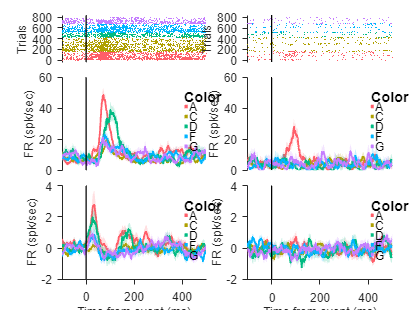

%% Figure: plot example neuron raster, example neuron sdf, and population sdf
% //// Fig 1a - Auditory cortex | Positive
sound_list = {'A','C','D','F','G'};

xlim_vals = [-100 500];
ylim_vals = [0 60];
clear single_unit_fig

% Auditory modulation //////////////////////////////////////////////////////
clear example_*
example_neuron = 1498;
example_valid_idx = strcmp(string(neuron_sdfsound_out{example_neuron}(:,5)) ,'nonviol');
example_sdf_in = cell2mat(neuron_sdfsound_out{example_neuron}(example_valid_idx,1));
example_raster_in = neuron_sdfsound_out{example_neuron}(example_valid_idx,2);
example_sound_cond = neuron_sdfsound_out{example_neuron}(example_valid_idx,3);
example_order_cond = neuron_sdfsound_out{example_neuron}(example_valid_idx,4);

clear pop_
pop_neurons_in = sig_units_auditory;
pop_sdf_in = [norm_fr_soundA(pop_neurons_in,:); norm_fr_soundC(pop_neurons_in,:); norm_fr_soundD(pop_neurons_in,:); norm_fr_soundF(pop_neurons_in,:); norm_fr_soundG(pop_neurons_in,:)];
pop_sound_cond = [repmat({'A'}, length(pop_neurons_in),1); repmat({'C'}, length(pop_neurons_in),1); repmat({'D'}, length(pop_neurons_in),1); repmat({'F'}, length(pop_neurons_in),1); repmat({'G'}, length(pop_neurons_in),1)];

single_unit_fig(1,1)=gramm('x',example_raster_in,'color',example_sound_cond);
single_unit_fig(1,1).geom_raster('geom',{'point'});
single_unit_fig(1,1).axe_property('XLim',xlim_vals);

single_unit_fig(2,1)=gramm('x',ops.sound_sdf_window,'y',example_sdf_in,'color',example_sound_cond);
single_unit_fig(2,1).stat_summary();
single_unit_fig(2,1).axe_property('XLim',xlim_vals,'YLim',ylim_vals);

single_unit_fig(3,1)=gramm('x',ops.sound_sdf_window,'y',pop_sdf_in,'color',pop_sound_cond);
single_unit_fig(3,1).stat_summary();
single_unit_fig(3,1).axe_property('XLim',xlim_vals,'YLim',[-2 4]);

% Frontal modulation //////////////////////////////////////////////////////
clear example_*
example_neuron = sig_units_frontal(21);
example_valid_idx = strcmp(string(neuron_sdfsound_out{example_neuron}(:,5)) ,'nonviol');
example_sdf_in = cell2mat(neuron_sdfsound_out{example_neuron}(example_valid_idx,1));
example_raster_in = neuron_sdfsound_out{example_neuron}(example_valid_idx,2);
example_sound_cond = neuron_sdfsound_out{example_neuron}(example_valid_idx,3);
example_order_cond = neuron_sdfsound_out{example_neuron}(example_valid_idx,4);

clear pop_
pop_neurons_in = sig_units_frontal;
pop_sdf_in = [norm_fr_soundA(pop_neurons_in,:); norm_fr_soundC(pop_neurons_in,:); norm_fr_soundD(pop_neurons_in,:); norm_fr_soundF(pop_neurons_in,:); norm_fr_soundG(pop_neurons_in,:)];
pop_sound_cond = [repmat({'A'}, length(pop_neurons_in),1); repmat({'C'}, length(pop_neurons_in),1); repmat({'D'}, length(pop_neurons_in),1); repmat({'F'}, length(pop_neurons_in),1); repmat({'G'}, length(pop_neurons_in),1)];

single_unit_fig(1,2)=gramm('x',example_raster_in,'color',example_sound_cond);
single_unit_fig(1,2).geom_raster('geom',{'point'});
single_unit_fig(1,2).axe_property('XLim',xlim_vals);

single_unit_fig(2,2)=gramm('x',ops.sound_sdf_window,'y',example_sdf_in,'color',example_sound_cond);
single_unit_fig(2,2).stat_summary();
single_unit_fig(2,2).axe_property('XLim',xlim_vals,'YLim',ylim_vals);

single_unit_fig(3,2)=gramm('x',ops.sound_sdf_window,'y',pop_sdf_in,'color',pop_sound_cond);
single_unit_fig(3,2).stat_summary();
single_unit_fig(3,2).axe_property('XLim',xlim_vals,'YLim',[-2 4]);


% Figure setup    ////////////////////////////////////////////////////////
single_unit_fig(1,1).axe_property('XTick',[],'XColor',[1 1 1]);
single_unit_fig(2,1).axe_property('XTick',[],'XColor',[1 1 1]);
single_unit_fig(1,2).axe_property('XTick',[],'XColor',[1 1 1]);
single_unit_fig(2,2).axe_property('XTick',[],'XColor',[1 1 1]);


single_unit_fig(1,1).geom_vline('xintercept',0,'style','k-');
single_unit_fig(2,1).geom_vline('xintercept',0,'style','k-');
single_unit_fig(3,1).geom_vline('xintercept',0,'style','k-');

single_unit_fig(1,2).geom_vline('xintercept',0,'style','k-');
single_unit_fig(2,2).geom_vline('xintercept',0,'style','k-');
single_unit_fig(3,2).geom_vline('xintercept',0,'style','k-');


single_unit_fig(1,1).set_names('y','Trials');
single_unit_fig(2,1).set_names('x','','y','FR (spk/sec)');
single_unit_fig(3,1).set_names('x','Time from event (ms)','y','FR (spk/sec)');

single_unit_fig(1,2).set_names('y','Trials');
single_unit_fig(2,2).set_names('x','','y','FR (spk/sec)');
single_unit_fig(3,2).set_names('x','Time from event (ms)','y','FR (spk/sec)');


% Figure layout ////////////////////////////////////////////////////////////
single_unit_fig(1,1).set_layout_options...
    ('Position',[0.15 0.8 0.35 0.15],... %Set the position in the figure (as in standard 'Position' axe property)
    'legend',false,...
    'margin_height',[0.00 0.00],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.0 0.00],...
    'redraw',false);

single_unit_fig(2,1).set_layout_options...
    ('Position',[0.15 0.45 0.35 0.3],... %Set the position in the figure (as in standard 'Position' axe property)
    'margin_height',[0.00 0.00],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.0 0.00],...
    'redraw',false);

single_unit_fig(3,1).set_layout_options...
    ('Position',[0.15 0.1 0.35 0.3],... %Set the position in the figure (as in standard 'Position' axe property)
    'margin_height',[0.00 0.00],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.0 0.00],...
    'redraw',false);

single_unit_fig(1,2).set_layout_options...
    ('Position',[0.6 0.8 0.35 0.15],... %Set the position in the figure (as in standard 'Position' axe property)
    'legend',false,...
    'margin_height',[0.00 0.00],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.0 0.00],...
    'redraw',false);

single_unit_fig(2,2).set_layout_options...
    ('Position',[0.6 0.45 0.35 0.3],... %Set the position in the figure (as in standard 'Position' axe property)
    'margin_height',[0.00 0.00],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.0 0.00],...
    'redraw',false);

single_unit_fig(3,2).set_layout_options...
    ('Position',[0.6 0.1 0.35 0.3],... %Set the position in the figure (as in standard 'Position' axe property)
    'margin_height',[0.00 0.00],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.0 0.00],...
    'redraw',false);

figure('Renderer', 'painters', 'Position', [100 100 800 600]);
single_unit_fig.draw();